# Confidence Regions Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path. To do so you can navigate to the StatBainz folder and fun the function addSB2path.m. Alternatively you can fill in the directory and run the code below.

statsbrainz_directory_pathloc = 'fill me in';
addpath(genpath(statsbrainz_directory_pathloc));

## Surface Confidence regions

sb_dir = statbrainz_maindir;
path4gifti_L = [sb_dir, 'BrainImages/Gifti_files/S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, 'BrainImages/Gifti_files/S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
load([sb_dir,'BrainImages/Real_data/hcpWM_surface.mat'])

#### Generate data

FWHM = 10; nsubj = 50;
clear data xbar mask
data = srf_noise(hcp_srf, FWHM, nsubj);

50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done
50 x 1 surfaces to smooth, % remaining: 100 90 80 70 60 50 40 30 20 10 0 Done


for hemis= {'lh', 'rh'}
    h = hemis{1};
    data.(h) = (data.(h))./std(data.(h)(:));
    data.(h) = (data.(h)).*hcp_data_std.(h);
    data.(h) = data.(h) + hcp_data_mean.(h);
    xbar.(h) = mean(data.(h),2);
    mask.(h) = ~isnan(xbar.(h));
end

## FDR cope sets

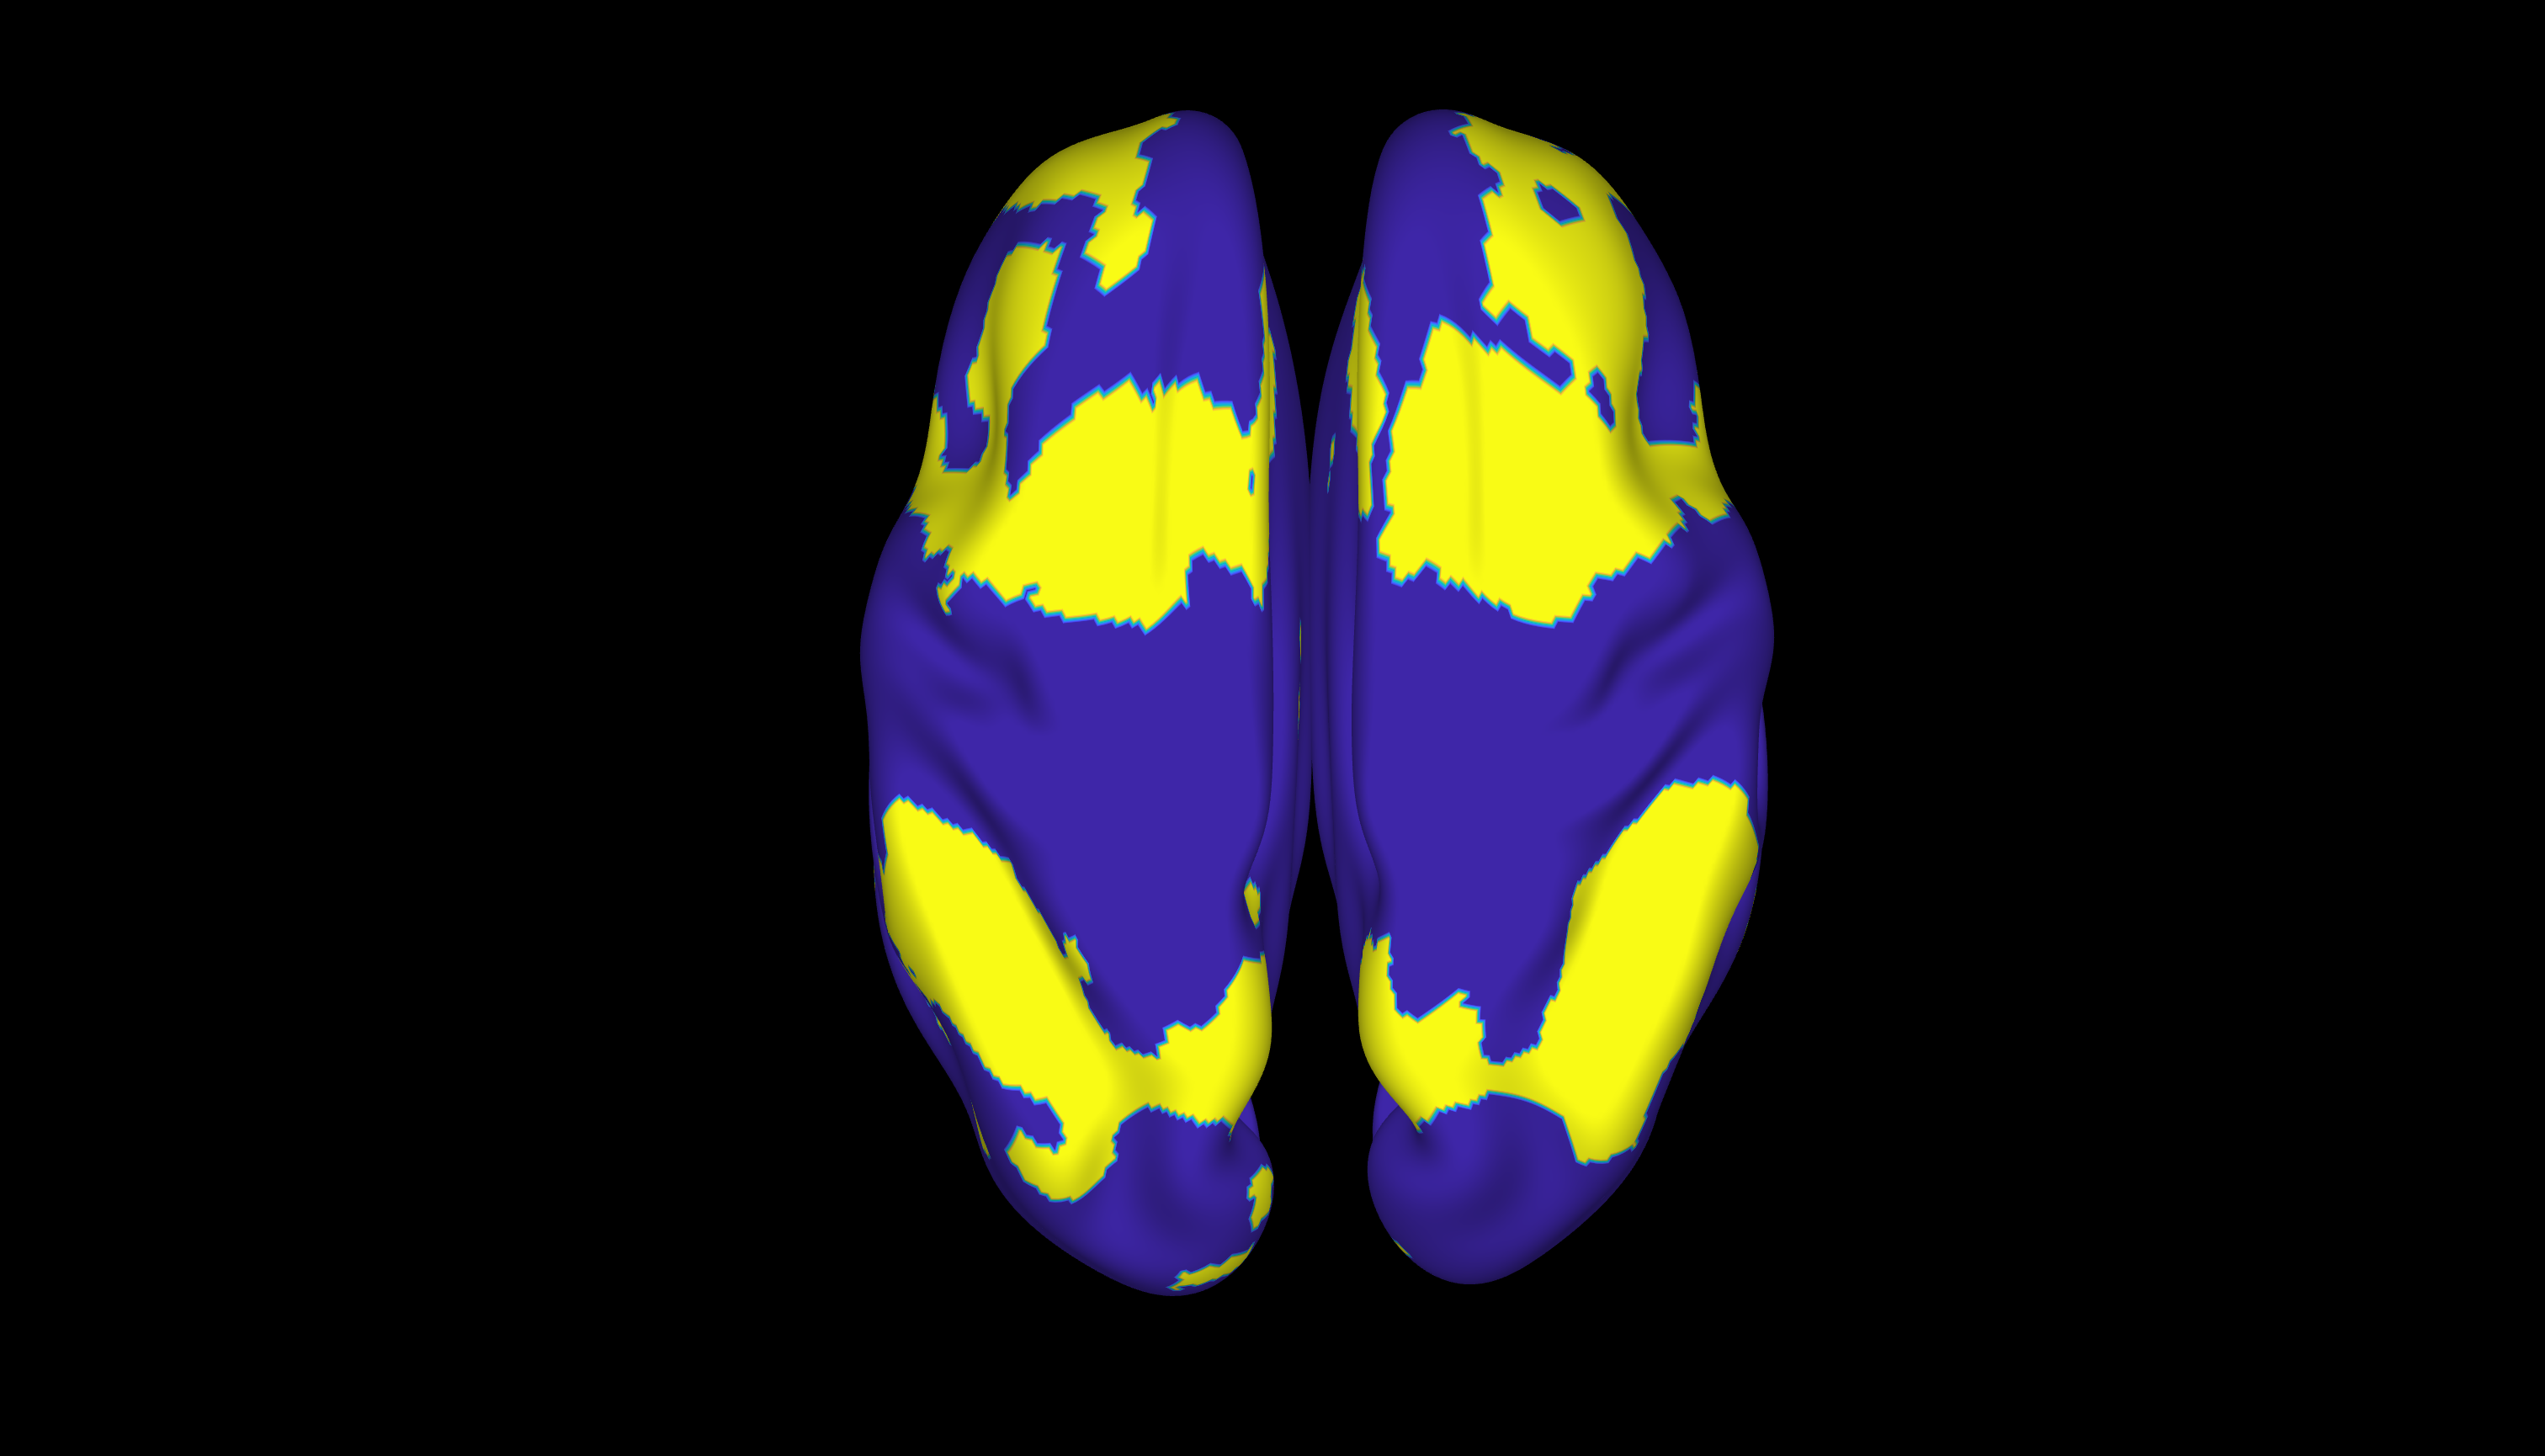

figure; set(gcf,'Visible','on')
c = 0;
[ lower_band_im, upper_band_im ] = srf_fdr_crs( data, mask, c );
srfplot(hcp_srf, upper_band_im)

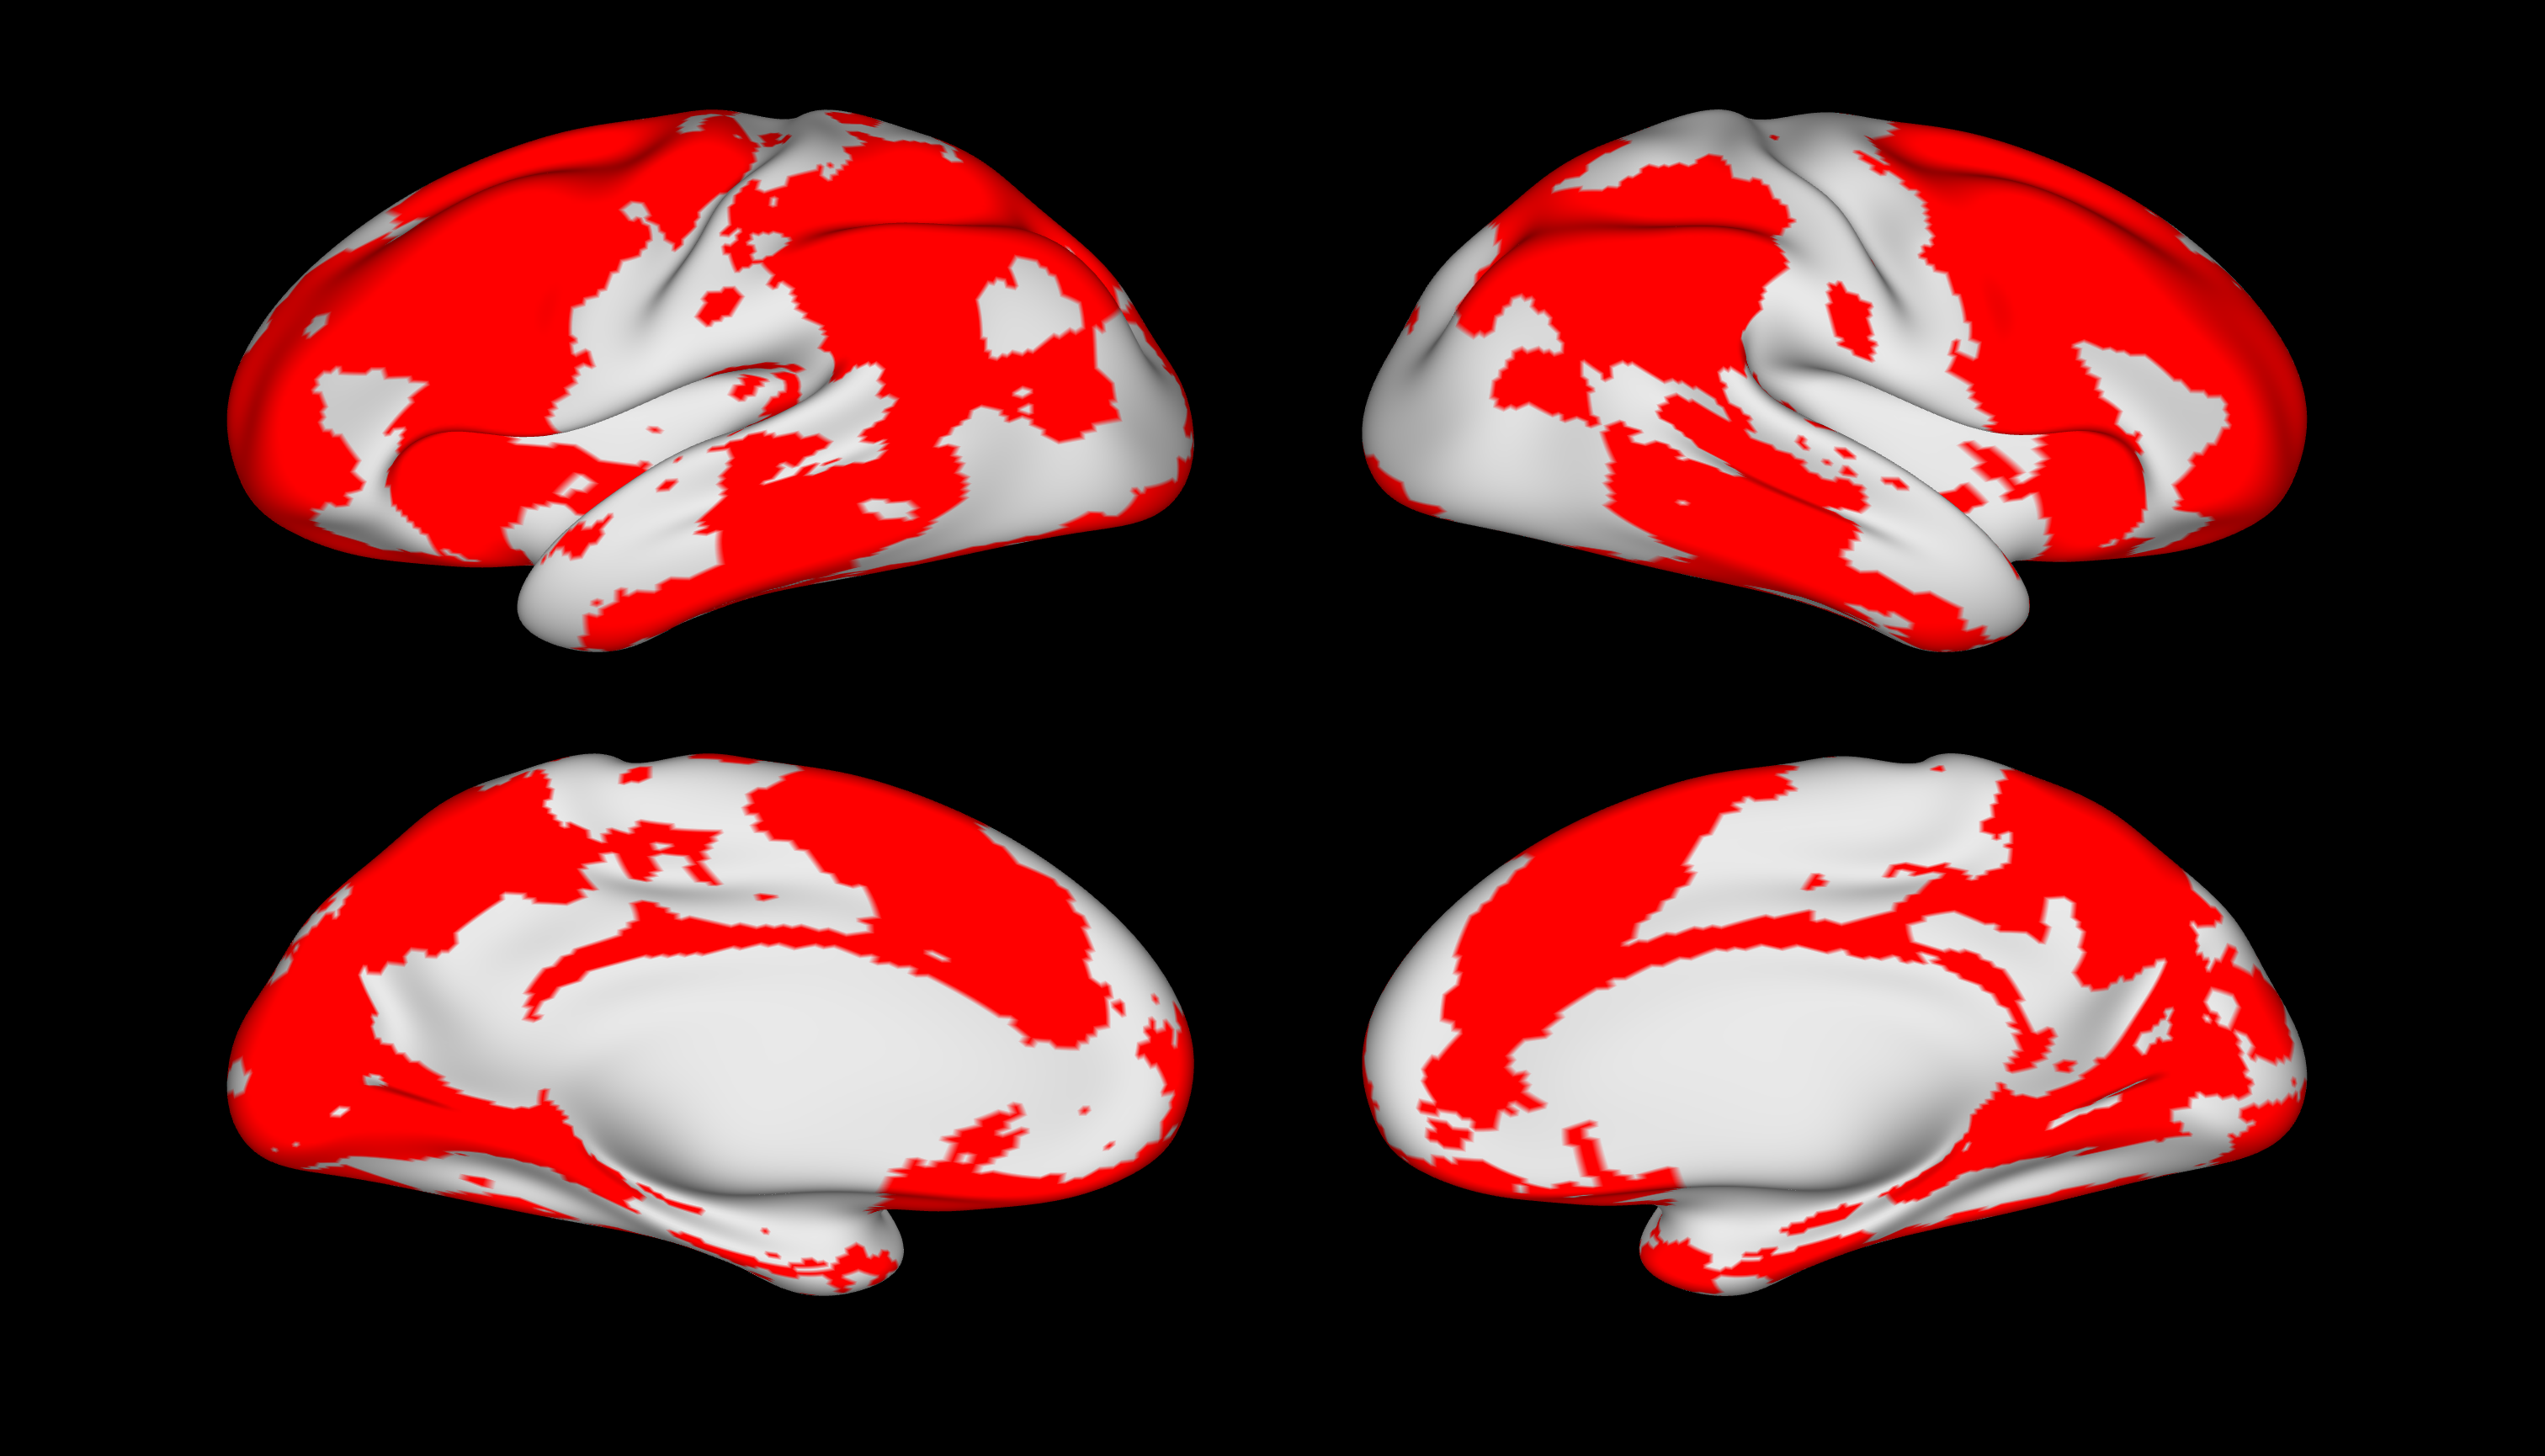


%srfplot(hcp_srf.lh, lower_band_im > c
t = tiledlayout(2,2,'TileSpacing','Compact');
xbar.lh = (xbar.lh).*mask.lh;
xbar.rh = (xbar.rh).*mask.rh;
for doback = [0,1]
    for hemis= {'lh', 'rh'}
        h = hemis{1};
        color_map = srf_color_crs( srf.(h), lower_band_im.(h), upper_band_im.(h), xbar.(h), c, 1, 'bowring', 0 );
        %color_map(1-mask.(h) > 0,:) = 1;
        nexttile;
        srfplot(hcp_srf.(h), color_map, doback)
        % srf_cope_display2( srf.(h), upper_band_im.(h) > c, lower_band_im.(h) > c, muhat.(h), c, doback, docontour);
    end
end
surfscreen

%srf_cope_display(hcp_srf.lh, lower_set, upper_set, xbar, c)

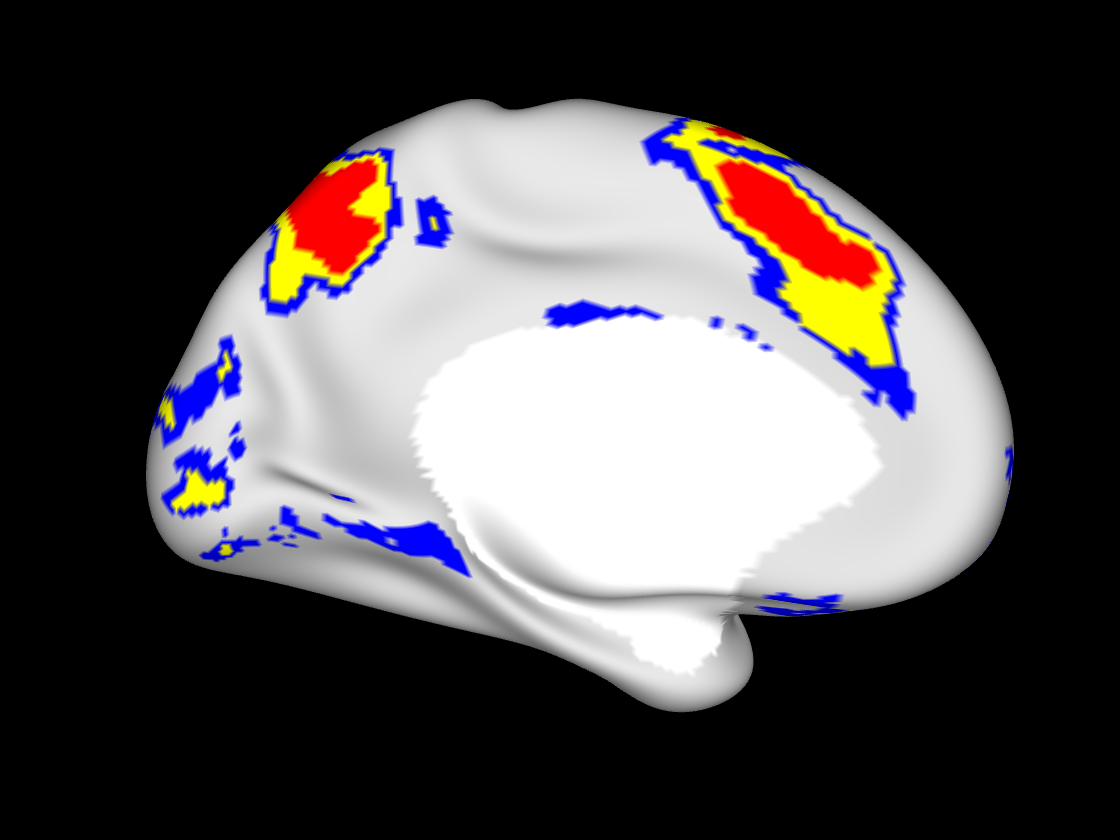

figure; set(gcf,'Visible','on')
c = 1;
clear tstats xbar upper_set lower_set
[tstats.lh, xbar.lh] = mvtstat(data.lh - c);
[tstats.rh, xbar.rh] = mvtstat(data.rh - c);
pvals_all = tstat2pval(nan2zero([tstats.rh, tstats.lh]), 50-1, 0);
pvals.lh = tstat2pval(tstats.lh, 50-1, 0);
pvals.rh = tstat2pval(tstats.rh, 50-1, 0);

[~,~,~,maxp] = fdrBH( pvals_all );
upper_set.lh = pvals.lh < maxp;
upper_set.rh = pvals.rh < maxp;

[~,~,~,maxp2] = fdrBH( 1-pvals_all );
lower_set.lh = (1-pvals.lh) > maxp2;
lower_set.rh = (1-pvals.rh) > maxp2;
srf_cope_display(hcp_srf.lh,lower_set.lh,upper_set.lh, xbar.lh, 0, 1)

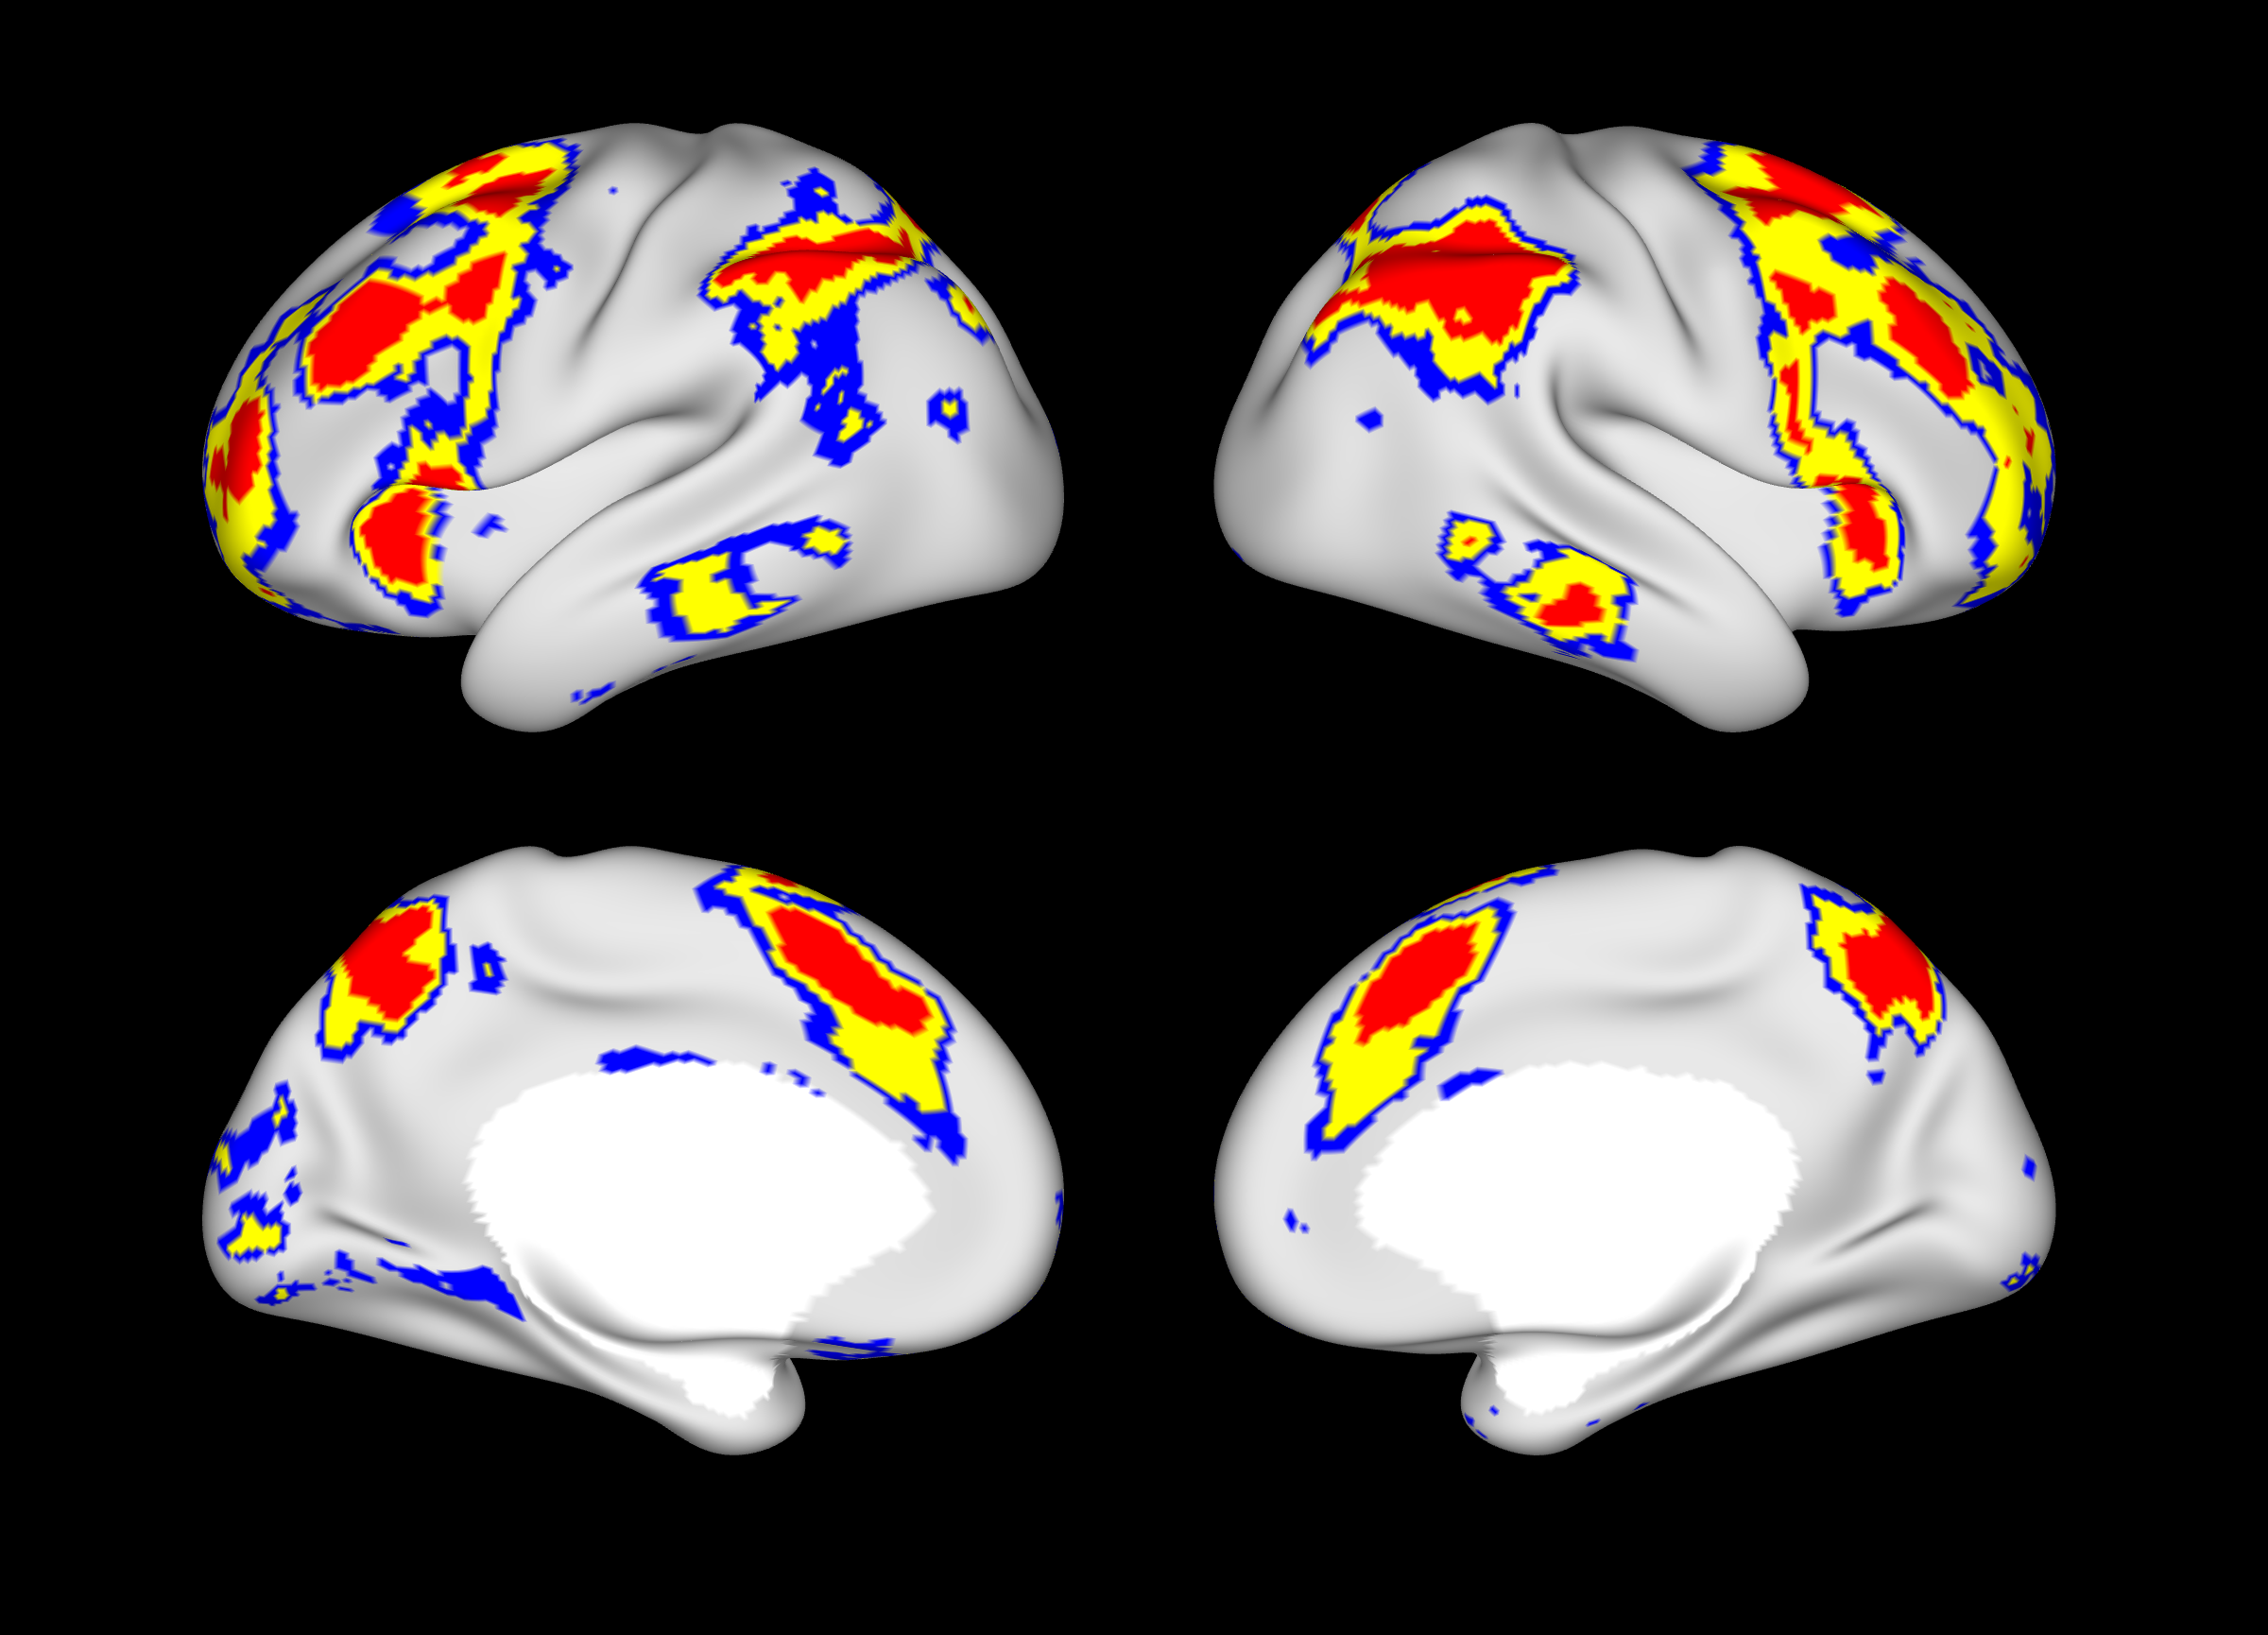

figure; set(gcf,'Visible','on')
t = tiledlayout(2,2,'TileSpacing','Compact');
for doback = [0,1]
    for hemis= {'lh', 'rh'}
        h = hemis{1};
        nexttile;
        srf_cope_display(hcp_srf.(h),lower_set.(h),upper_set.(h), xbar.(h), 0, doback)
        %color_map = srf_color_crs( srf.(h), lower_set.(h), upper_set.(h), muhat.(h), c, 1, 'bowring', 0 );
        %color_map(1-intersection_mask.(h) > 0,:) = 1;
        %
        %srfplot(srf.(h), color_map, doback)
        % srf_cope_display2( srf.(h), upper_band_im.(h) > c, lower_band_im.(h) > c, muhat.(h), c, doback, docontour);
    end
end
surfscreen

## Simultaneous Confidence Regions

[ lower_band, upper_band ] = scopes( data, 1000, 0.05, 1);

Error using sum
Invalid data type. First argument must be numeric or logical.
Error in mean (line 122)
            y = sum(x, dim, flag) ./ mysize(x,dim);
Error in scopes (line 57)
data_mean = mean(data, D+1);

c = 2;
[ lower_set, upper_set, contour ] = srf_scb2cope( hcp_srf.lh, lower_band, upper_band, xbar, c );

Unrecognized function or variable 'lower_band'.

[ upper_set2, lower_set2, contour2 ] = srf_scb2cope( hcp_srf.lh, -lower_band, -upper_band, -xbar, c );

figure; clf; set(gcf,'Visible','on')
color_map1 = srf_colour(hcp_srf.lh, {lower_set, upper_set, contour}, {[1,0.5,0.5], [0.9,0,0], [1,1,0]}, 0);
color_map2 = srf_colour(hcp_srf.lh, {lower_set2, upper_set2, contour2}, {[1,0.5,0.5], [0.9,0,0], [1,1,0]}, 0);
%srfplot(hcp_srf.lh, color_map1)

figure; set(gcf,'Visible','on')

lower_intersection = lower_set.*lower_set2 >0;
lower_just1 = lower_set - lower_intersection >0;
lower_just2 = lower_set2 - lower_intersection >0;

sets = {lower_intersection, lower_just1, lower_just2, upper_set, upper_set2};
colours = {[0.93 0.51 0.93]*0.9, [1,0.5,0.5], [0.5,0.5, 1], [0.9,0,0], [0,0,0.9]};
color_map = srf_colour(hcp_srf.lh, sets, colours);
srfplot(hcp_srf.lh, color_map)

srfplot(hcp_srf.lh, lower_set2)